Геометрические параметры

clear all;
a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

K = 0;
T_a = 1;
theta_2 = linspace(0, pi/3, 100);

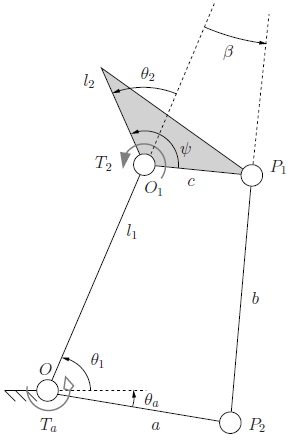

Определение контактных сил в зависимости от конфигурации

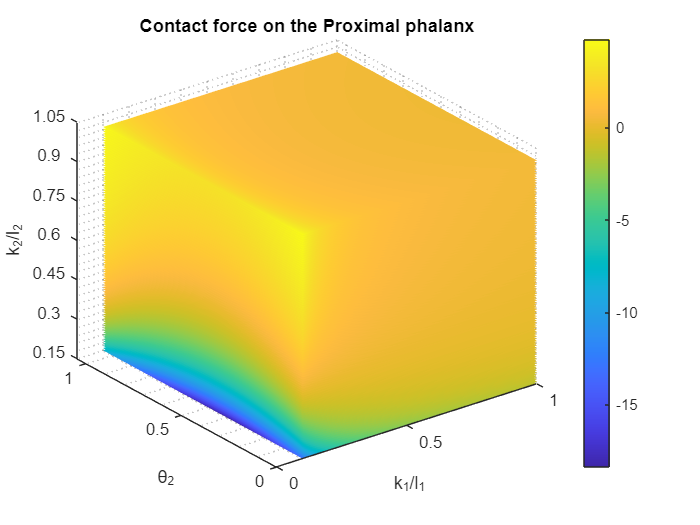

x = linspace(0.1, l_1, size(theta_2,2));
y = theta_2;
z = linspace(0.1, l_2, size(theta_2,2));


[X,Y,Z] = ndgrid(x,y,z);
[F_1, F_2] = contactForces(a,b,c,l_1,psi,K,T_a,X,Y,Z);

f1 = figure;
f2 = figure;

figure(f1);
hold on;
for i = 1:size(x,2)
    surf(X(:,:,i),Y(:,:,i),Z(:,:,i),F_1(:,:,i)) ;
end
grid minor;
view(3);
shading interp
title('Contact force on the Proximal phalanx');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');
colorbar;
ax=gca;
ax.XTickLabel= ax.XTick/l_1;
ax.ZTickLabel= ax.ZTick/l_2;

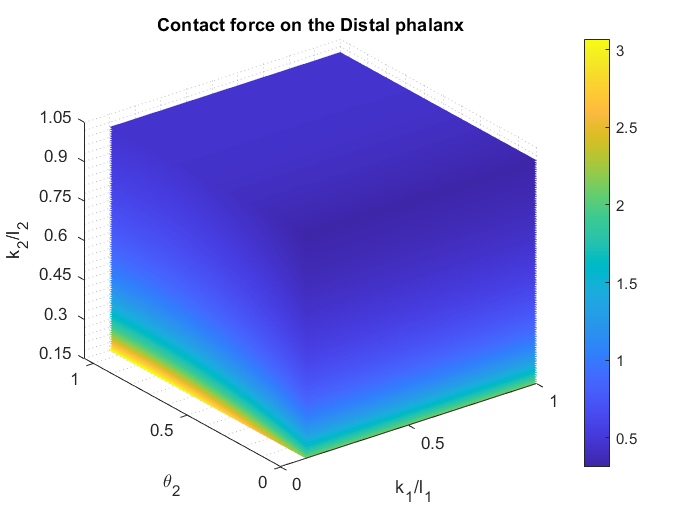


figure(f2);
hold on
for i = 1:size(x,2)
    surf(X(:,:,i),Y(:,:,i),Z(:,:,i),F_2(:,:,i)) ;
end
grid minor;
view(3);
shading interp
title('Contact force on the Distal phalanx');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');
colorbar;
ax=gca;
ax.XTickLabel = ax.XTick/l_1;
ax.ZTickLabel = ax.ZTick/l_2;

Поиск конфигураций, соответствующих f_1 = f_2

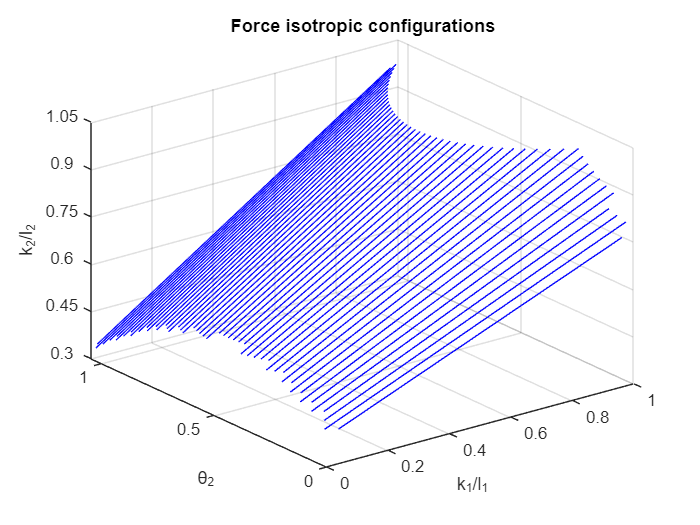

clear all;
syms k_2 k_1 theta_2;
a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

K = 0;
T_a = 1;
theta_2 = linspace(0, pi/3, 50);

f3 = figure;
figure(f3);
for i = theta_2
    syms k_2 k_1;
    [F_1, F_2] = contactForces(a, b, c, l_1, psi, K, T_a, k_1, i, k_2);
    
    k_2 = linspace(0.1, l_2, 50);
    [sol_1, parameters, conditions] = solve(F_1==F_2, k_1,'ReturnConditions',true);
    k_1 = subs(sol_1);
    
    L1 = vpa(conditions);
    L2 = k_1 > 0;
    L3 = k_1 < l_1;
    L4 = k_2 > 0;
    L5 = k_2 < l_2;

    L = logical(L1 & L2 & L3 & L4 & L5);
    
    k_1 = double(k_1(L));
    k_2 = double(k_2(L));
    thet2 = i*ones(1, size(k_2, 2));
    plot3(k_1, thet2, k_2, '-b');    
    hold on;
end

grid on;
title('Force isotropic configurations');
xlabel('k_1/l_1');
ylabel('\theta_2');
zlabel('k_2/l_2');

ax=gca;
ax.XTickLabel = ax.XTick/l_1;
ax.ZTickLabel = ax.ZTick/l_2;

Поиск и визуализация устойчивых конфигураций захвата

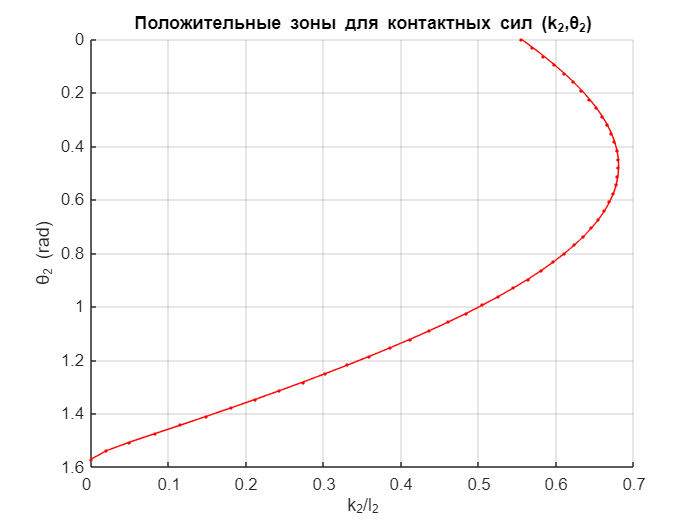

clear all;

a = 0.3348; b = 1.0; c = 1/3;
l_1 = 1; l_2 = l_1;
psi = pi/2;

theta_2_max = pi/2;
theta_2_min = 0;

k_2_min = 0.001;
k_2_max = l_2;

% Оптимальные параметры в URH
% a = 3/4; b = 1; c = 1/3;
% l_1 = 1; l_2 = 3/4;
% psi = pi/180*54;

K = 0;
T_a = 1;
k_1 = 1; % к1 не имеет значения, так как важен знак f1 и f2, а к1 в знаменателе. Для удобства k1=1

% Сетка Grasp-state plane 
theta_2 = linspace(theta_2_min, theta_2_max, 50);
k_2 = linspace(0.01, l_2, 20);

clear f4;
f4 = figure;
hold on;
grid on;
title('Положительные зоны для контактных сил (k_2,\theta_2)');
xlabel('k_2/l_2');
ylabel('\theta_2 (rad)');
% xlim([0 l_2]);

axis ij; % Разворот оси y - смещение начала координат

% for i = theta_2
%     for j = k_2
%         [f_1, f_2] = contactForces(a, b, c, l_1, psi, K, T_a, k_1, i, j);
%         f_1 = double(subs(f_1));
%         f_2 = double(subs(f_2));
% 
%         % Условия устойчивости захвата
%         L1 = f_1 >= 0;
%         L2 = f_2 >= 0;
%         L = L1 & L2;
% 
%         figure(f4);
%         if (L)
%             % Визуализация зоны устойчивого захвата
%             plot(j, i, 'Marker','+','Color','m');
%         else
%             % % Визуализация зоны неустойчивого захвата
%             plot(j, i, 'Marker','*','Color','k');
%         end
%     end
%     clear k_2pos angPos k_2neg angNeg
% end
    
% График траектории для f_1 = 0 - граница раздела между устойчивой
% зоной и неустойчивой: k2 = h*cos(theta_2)
ax=gca;
ax.XTickLabel = ax.XTick/l_2; % Изменение масштаба по оси Х в 1/l_2 раз
figure(f4);
k_2 = equilibriumCurve(a, b, c, l_1, psi, theta_2);
plot(k_2,theta_2, 'Marker','.','Color','r');

**Построение траекторий контакта при контакте дистальной фалангой**

syms k_2 k_2i theta_2 theta_2i;

f = contactRestriction(k_2,theta_2,k_2i,theta_2i, l_1);
theta_2 = solve(f==0, theta_2);

% f5 = figure;
% hold on;
% f6 = figure;
% hold on;
theta_2i = linspace(0, pi/2, 5);
k_2i = linspace(0.001, l_2, 5);
[X, Y] = ndgrid(k_2i, theta_2i);
k_2i = X; theta_2i = Y;

for i = 1:(size(X,1)*size(X,2))
    k_2i = X(i); theta_2i = Y(i);

    % acos дает два решения. Берем второе, соответствующее angle = +acos(...)
    theta_22 = subs(theta_2(2,:));

    k_2 = linspace(0.001, l_2, 1000);
    ang = double(subs(theta_22));

    k = 1;
    flag = 0;
    for j = 1:size(ang,2)
        if isreal(ang(j)) && ang(j) >= 0 && ang(j) <= pi/2
            k_22(k) = k_2(j);
            ang_22(k) = ang(j);  
            cos_ang_22(k) = cos(ang(j));
            flag = 1;

            k = k + 1;
        end
    end         
    
    % Проверка, что для выбранных н.у. существует траектория контакта 
    if flag && (size(k_22,2) > 1)
        figure(f4);    
        plot(k_22, ang_22);
%         plot(k_2i, theta_2i, 'Marker','*');
        
%         figure(f6);
%         hold on;
%         plot(k_22, cos_ang_22);
%         plot(k_2i, cos(theta_2i), 'Marker','*'); % Обозначение начальных условий, для которых получена траектория
    end
    clear k_22 ang_22 cos_ang_22;
end

**Поиск Paradoxical point**

Paradoxical point - это точка, разделяющая кривую равновесия на две части: часть кривой ниже этой точки притягивает контактные траектории, а часть кривой выше этой точки отталкивает от себя. Т.е. если контактные траектории пересекают кривую равновесия ниже Paradoxical point, то захват будет устойчивым. Если контактные траектории не пересекают кривую равновесия ниже линии равновесия, то захват будет неустойчивым.

Точкой перехода между устойчивой и неустойчивой частями кривой равновесия является Paradoxical point. 

Она соответсвует точке, в которой контактная траектория и кривая равновесия касательны, их производные в этой точке равны, т.е  f1'(k2, theta_2) = f2(k2, theta_2)'.

[out, fval] = paradoxicalCoord(a, b, c, l_1, psi);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


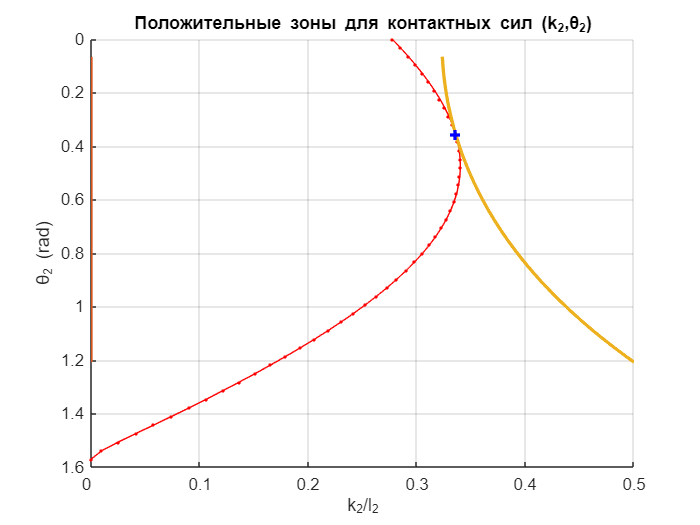

% Отрисовка траектории, соответствующей найденным условиям 
k_2i = out(3); theta_2i = 0; % Н.У. контактной траектории
syms k_2 theta_2;

f = singlePointContactTrajectory(k_2, theta_2, k_2i, theta_2i, l_1);
theta_2 = solve(f==0, theta_2); % Параметрическое определение кривой в форме theta_2=f(k_2)

k_2 = linspace(0.001, k_2_max, 1000); % 0.001 для избежания деления на 0
ang = double(subs(theta_2));

k = 1;
flag = 0;
% Определение точек с реальными координатами. Решения могут быть комплексными
for jj = 1:size(ang,1)
    for j = 1:size(ang,2)
        if isreal(ang(jj,j)) && ang(jj,j) >= 0 && ang(jj,j) <= pi/2
            k_22(jj,k) = k_2(j);
            ang_22(k) = ang(jj,j);  
            flag = 1;
    
            k = k + 1;
        end
    end         
end
% Проверка, что для выбранных н.у. существует траектория контакта 
if flag && (size(k_22,2) > 1)
    figure(f4);    
    plot(k_22, ang_22, 'LineWidth', 2);
end

% Отображение Paradoxical point
plot(out(1), out(2), '+b', 'LineWidth', 2);

Подсчет критерия стабильности захвата в пространстве Grasp-State Plane

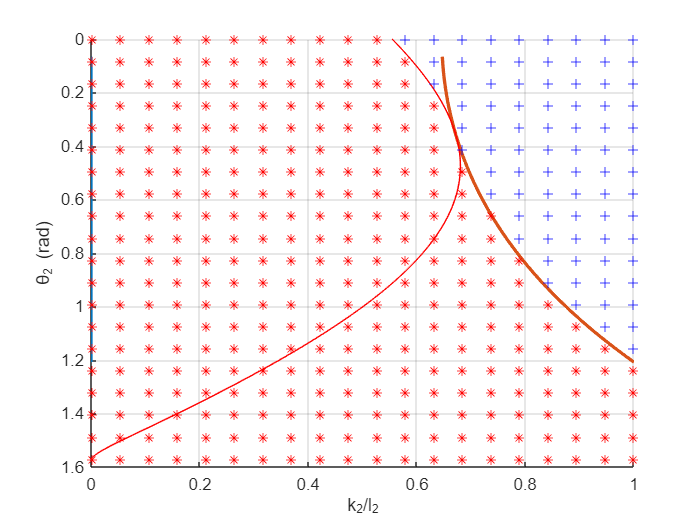

clear f5;
f5 = figure;
hold on;
grid on;
xlabel('k_2/l_2');
ylabel('\theta_2 (rad)');

axis ij; % Разворот оси y - смещение начала координат

k_2i = out(3); theta_2i = 0; % Н.У. контактной траектории
syms k_2 theta_2;

f = singlePointContactTrajectory(k_2,theta_2,k_2i,theta_2i, l_1);
theta_2 = solve(f==0, theta_2); % Параметрическое определение кривой в форме theta_2=f(k_2)

k_2 = linspace(0.001, k_2_max, 1000); % 0.001 для избежания деления на 0
ang = double(subs(theta_2));

k = 1;
flag = 0;
% Определение точек с реальными координатами. Решения могут быть комплексными
for jj = 1:size(ang,1)
    for j = 1:size(ang,2)
        if isreal(ang(jj,j)) && ang(jj,j) >= 0 && ang(jj,j) <= pi/2
            k_22(jj,k) = k_2(j);
            ang_22(k) = ang(jj,j);  
            flag = 1;
    
            k = k + 1;
        end
    end         
end
% Проверка, что для выбранных н.у. существует траектория контакта 
if flag && (size(k_22,2) > 1)
    figure(f5);    
    plot(k_22, ang_22, 'LineWidth', 2);
end
theta_2 = linspace(theta_2_min,theta_2_max,1000);
k_2 = equilibriumCurve(a, b, c, l_1, psi, theta_2);
plot(k_2,theta_2, 'LineStyle','-','Color','r');

syms k_2 theta_2;
k_2i = out(3);
theta_2i = 0;

f1 = equilibriumCurve(a, b, c, l_1, psi, theta_2);
f2 = solve(singlePointContactTrajectory(k_2, theta_2, k_2i, theta_2i, l_1)==0, theta_2);
% f2 = f2(2); % theta_2 = pi-acos(...)
k_2_set = linspace(k_2_min+0.001,k_2_max,20);
theta_2_set = linspace(theta_2_min,theta_2_max,20);

k_2_tang = out(1);
theta_2_tang = out(2);

count_stable = 0;
count_nonstable = 0;
for k=k_2_set
    for t=theta_2_set
    L1 = logical(k <= double(subs(f1,theta_2,t)));
    L2 = logical(t >= min(double(subs(f2,k_2,k)))) || ~isreal(min(double(subs(f2,k_2,k))));
    L3 = logical(t >= theta_2_tang);
    
    if L1 || (L2 && L3)
        plot(k, t, '*r');
        count_stable = count_stable + 1;
    else
        count_nonstable = count_nonstable + 1;
        plot(k, t, '+b');
    end
    end
end

% Коэффициент стабильности - процент стабильных конфигураций захвата
mu = count_stable / (count_stable+count_nonstable)

mu = 0.7950